# Feedforward ARX Models

Pieter Leon van den Berg

22684166

14 August 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Feedforward ARX Models

Fit ARX models to the copper solvent extraction model to use for the feedforward controller tuning

## Setup

### MATLAB Simulink

clear;
clc;

### Plot colours

orange = '#FF9A5B';
blue   = '#06ACE9';

## ARX Properties

% Loop for gamma from 0 to 4000
gamma_bound = 4000; 

## Step in f_PLSP

### Read the Step Data

STEP_f_PLSP_TABLE = readtable('controller_tuning/data/feedforward/feedforward_step_f_PLSP.csv');

### Extract the Data

% Extract the model time
STEP_f_PLSP_time          = STEP_f_PLSP_TABLE.Time;

% Extract the disturbance variable
STEP_f_PLSP_f_PLSP        = STEP_f_PLSP_TABLE.f_PLSP_measured;

% Extract the controlled variable
STEP_f_PLSP_c_LO_measured = STEP_f_PLSP_TABLE.c_LO_measured;

### Deviation variable form

% Disturbance variable
STEP_f_PLSP_f_PLSP_prime  = STEP_f_PLSP_f_PLSP - STEP_f_PLSP_f_PLSP(1);

% Controlled variables
STEP_f_PLSP_c_LO_measured_prime = STEP_f_PLSP_c_LO_measured - STEP_f_PLSP_c_LO_measured(1);

### Time step

STEP_f_PLSP_delta_t = STEP_f_PLSP_time(2) - STEP_f_PLSP_time(1);    % [s]

### Time in Hours

STEP_f_PLSP_time_hours = STEP_f_PLSP_time / (60*60);                % [h]

## Change in c_LO

### ARX model

for STEP_f_PLSP_c_LO_gamma = 0:gamma_bound  
    % Set up the system
    STEP_f_PLSP_c_LO_U = [STEP_f_PLSP_c_LO_measured_prime((1+STEP_f_PLSP_c_LO_gamma):(end-1)), STEP_f_PLSP_f_PLSP_prime(1:(end-1-STEP_f_PLSP_c_LO_gamma))];
    STEP_f_PLSP_c_LO_z = STEP_f_PLSP_c_LO_measured_prime((2+STEP_f_PLSP_c_LO_gamma):end);
    
    % Perform the linear regression
    STEP_f_PLSP_c_LO_w = STEP_f_PLSP_c_LO_U\STEP_f_PLSP_c_LO_z;
    STEP_f_PLSP_c_LO_a = STEP_f_PLSP_c_LO_w(1);
    STEP_f_PLSP_c_LO_b = STEP_f_PLSP_c_LO_w(2);
    
    % Calcalate the predicted values
    STEP_f_PLSP_c_LO_predicted = STEP_f_PLSP_c_LO_U*STEP_f_PLSP_c_LO_w;
    
    % Calculate the MSE
    STEP_f_PLSP_c_LO_MSE(STEP_f_PLSP_c_LO_gamma+1) = mean((STEP_f_PLSP_c_LO_predicted - STEP_f_PLSP_c_LO_z).^2);
    
    % Calculate the transfer function constants
    STEP_f_PLSP_c_LO_tau(STEP_f_PLSP_c_LO_gamma+1)   = (-STEP_f_PLSP_delta_t)/log(STEP_f_PLSP_c_LO_a);
    STEP_f_PLSP_c_LO_Kp(STEP_f_PLSP_c_LO_gamma+1)    = (STEP_f_PLSP_c_LO_b)/(1-STEP_f_PLSP_c_LO_a);
    STEP_f_PLSP_c_LO_theta(STEP_f_PLSP_c_LO_gamma+1) = (STEP_f_PLSP_c_LO_gamma)*(STEP_f_PLSP_delta_t);
    
end

### Find the optimal gamma value

% Find the optimal gamma value
STEP_f_PLSP_c_LO_gamma_optimal_index = find(STEP_f_PLSP_c_LO_MSE == min(STEP_f_PLSP_c_LO_MSE));

% Find the optimal transfer function values
STEP_f_PLSP_c_LO_gamma_optimal = STEP_f_PLSP_c_LO_gamma_optimal_index - 1;
STEP_f_PLSP_c_LO_tau_optimal   = STEP_f_PLSP_c_LO_tau(STEP_f_PLSP_c_LO_gamma_optimal_index);
STEP_f_PLSP_c_LO_Kp_optimal    = STEP_f_PLSP_c_LO_Kp(STEP_f_PLSP_c_LO_gamma_optimal_index);
STEP_f_PLSP_c_LO_theta_optimal = STEP_f_PLSP_c_LO_theta(STEP_f_PLSP_c_LO_gamma_optimal_index);

### Simulate the transfer function using Simulink

% Setup the Simulink transfer functions
simulink_Kp    = STEP_f_PLSP_c_LO_Kp_optimal;
simulink_tau   = STEP_f_PLSP_c_LO_tau_optimal;
simulink_theta = STEP_f_PLSP_c_LO_theta_optimal;

% Feed the data to Simulink
simulink_feed    = [STEP_f_PLSP_time STEP_f_PLSP_f_PLSP_prime];
simulink_results = sim('controller_tuning/arx_models/arx_models.slx');

% Extract the Simulink transfer function fit
STEP_f_PLSP_c_LO_transfer_function_results    = simulink_results.transfer_function_results.Data;
STEP_f_PLSP_c_LO_transfer_function_time       = simulink_results.tout;
STEP_f_PLSP_c_LO_transfer_function_time_hours = simulink_results.tout / (60*60);

### Plot the ARX model of f_PLSP and c_LO

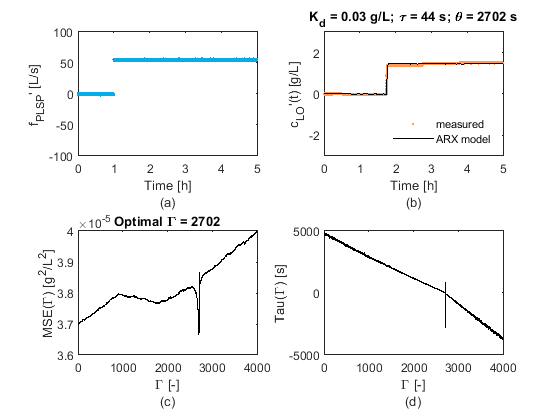

% Create the group of f_PLSP and c_LO
figure()

% PLot f_PLSP
subplot(2,2,1)
plot(STEP_f_PLSP_time_hours, STEP_f_PLSP_f_PLSP_prime, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("f_{PLSP}' [L/s]")
xlabel({"Time [h]";"(a)"})
ylim([-100 100])
xlim([0 STEP_f_PLSP_time_hours(end)])

% Plot c_LO_measured
subplot(2,2,2)
plot(STEP_f_PLSP_time_hours, STEP_f_PLSP_c_LO_measured_prime, '.', 'MarkerSize', 6 ,'Color', orange)
hold on
plot(STEP_f_PLSP_c_LO_transfer_function_time_hours, STEP_f_PLSP_c_LO_transfer_function_results, 'k-','LineWidth', 1)
hold off
STEP_f_PLSP_c_LO_title = sprintf('K_d = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', STEP_f_PLSP_c_LO_Kp_optimal, STEP_f_PLSP_c_LO_tau_optimal, STEP_f_PLSP_c_LO_theta_optimal);
title(STEP_f_PLSP_c_LO_title)
legend({'measured', 'ARX model'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{LO}'(t) [g/L]")
xlabel({"Time [h]";"(b)"})
ylim([-3 3])
xlim([0 STEP_f_PLSP_time_hours(end)])

% Plot the MSE
subplot(2,2,3)
plot([0:gamma_bound], STEP_f_PLSP_c_LO_MSE, 'k-','LineWidth', 1)
STEP_f_PLSP_c_LO_MSE_title = sprintf('Optimal \\Gamma = %.0f', STEP_f_PLSP_c_LO_gamma_optimal);
title(STEP_f_PLSP_c_LO_MSE_title)
ylabel("MSE(\Gamma) [g^{2}/L^{2}]")
xlabel({"\Gamma [-]";"(c)"})
xlim([0 gamma_bound])

% Plot gamma
subplot(2,2,4)
plot([0:gamma_bound], STEP_f_PLSP_c_LO_tau, 'k-','LineWidth', 1)
ylabel("Tau(\Gamma) [s]")
xlabel({"\Gamma [-]";"(d)"})
xlim([0 gamma_bound])

% Save the current figure
print('controller_tuning/output/feedforward/step_f_PLSP_c_LO_prime_ARX_model', '-dpng', '-r600')

## Step in f_PLSS

### Read the Step Data

STEP_f_PLSS_TABLE = readtable('controller_tuning/data/feedforward/feedforward_step_f_PLSS.csv');

### Extract the Data

% Extract the model time
STEP_f_PLSS_time          = STEP_f_PLSS_TABLE.Time;

% Extract the disturbance variable
STEP_f_PLSS_f_PLSS        = STEP_f_PLSS_TABLE.f_PLSS_measured;

% Extract the controlled variable
STEP_f_PLSS_c_LO_measured = STEP_f_PLSS_TABLE.c_LO_measured;

### Deviation variable form

% Disturbance variable
STEP_f_PLSS_f_PLSS_prime  = STEP_f_PLSS_f_PLSS - STEP_f_PLSS_f_PLSS(1);

% Controlled variables
STEP_f_PLSS_c_LO_measured_prime = STEP_f_PLSS_c_LO_measured - STEP_f_PLSS_c_LO_measured(1);

### Time step

STEP_f_PLSS_delta_t = STEP_f_PLSS_time(2) - STEP_f_PLSS_time(1);    % [s]

### Time in Hours

STEP_f_PLSS_time_hours = STEP_f_PLSS_time / (60*60);                % [h]

## Change in c_LO

### ARX model

for STEP_f_PLSS_c_LO_gamma = 0:gamma_bound  
    % Set up the system
    STEP_f_PLSS_c_LO_U = [STEP_f_PLSS_c_LO_measured_prime((1+STEP_f_PLSS_c_LO_gamma):(end-1)), STEP_f_PLSS_f_PLSS_prime(1:(end-1-STEP_f_PLSS_c_LO_gamma))];
    STEP_f_PLSS_c_LO_z = STEP_f_PLSS_c_LO_measured_prime((2+STEP_f_PLSS_c_LO_gamma):end);
    
    % Perform the linear regression
    STEP_f_PLSS_c_LO_w = STEP_f_PLSS_c_LO_U\STEP_f_PLSS_c_LO_z;
    STEP_f_PLSS_c_LO_a = STEP_f_PLSS_c_LO_w(1);
    STEP_f_PLSS_c_LO_b = STEP_f_PLSS_c_LO_w(2);
    
    % Calcalate the predicted values
    STEP_f_PLSS_c_LO_predicted = STEP_f_PLSS_c_LO_U*STEP_f_PLSS_c_LO_w;
    
    % Calculate the MSE
    STEP_f_PLSS_c_LO_MSE(STEP_f_PLSS_c_LO_gamma+1) = mean((STEP_f_PLSS_c_LO_predicted - STEP_f_PLSS_c_LO_z).^2);
    
    % Calculate the transfer function constants
    STEP_f_PLSS_c_LO_tau(STEP_f_PLSS_c_LO_gamma+1)   = (-STEP_f_PLSS_delta_t)/log(STEP_f_PLSS_c_LO_a);
    STEP_f_PLSS_c_LO_Kp(STEP_f_PLSS_c_LO_gamma+1)    = (STEP_f_PLSS_c_LO_b)/(1-STEP_f_PLSS_c_LO_a);
    STEP_f_PLSS_c_LO_theta(STEP_f_PLSS_c_LO_gamma+1) = (STEP_f_PLSS_c_LO_gamma)*(STEP_f_PLSS_delta_t);
    
end

### Find the optimal gamma value

% Find the optimal gamma value
STEP_f_PLSS_c_LO_gamma_optimal_index = find(STEP_f_PLSS_c_LO_MSE == min(STEP_f_PLSS_c_LO_MSE));

% Find the optimal transfer function values
STEP_f_PLSS_c_LO_gamma_optimal = STEP_f_PLSS_c_LO_gamma_optimal_index - 1;
STEP_f_PLSS_c_LO_tau_optimal   = STEP_f_PLSS_c_LO_tau(STEP_f_PLSS_c_LO_gamma_optimal_index);
STEP_f_PLSS_c_LO_Kp_optimal    = STEP_f_PLSS_c_LO_Kp(STEP_f_PLSS_c_LO_gamma_optimal_index);
STEP_f_PLSS_c_LO_theta_optimal = STEP_f_PLSS_c_LO_theta(STEP_f_PLSS_c_LO_gamma_optimal_index);

### Simulate the transfer function using Simulink

% Setup the Simulink transfer functions
simulink_Kp    = STEP_f_PLSS_c_LO_Kp_optimal;
simulink_tau   = STEP_f_PLSS_c_LO_tau_optimal;
simulink_theta = STEP_f_PLSS_c_LO_theta_optimal;

% Feed the data to Simulink
simulink_feed    = [STEP_f_PLSS_time STEP_f_PLSS_f_PLSS_prime];
simulink_results = sim('controller_tuning/arx_models/arx_models.slx');

% Extract the Simulink transfer function fit
STEP_f_PLSS_c_LO_transfer_function_results    = simulink_results.transfer_function_results.Data;
STEP_f_PLSS_c_LO_transfer_function_time       = simulink_results.tout;
STEP_f_PLSS_c_LO_transfer_function_time_hours = simulink_results.tout / (60*60);

### Plot the ARX model of f_PLSS and c_LO

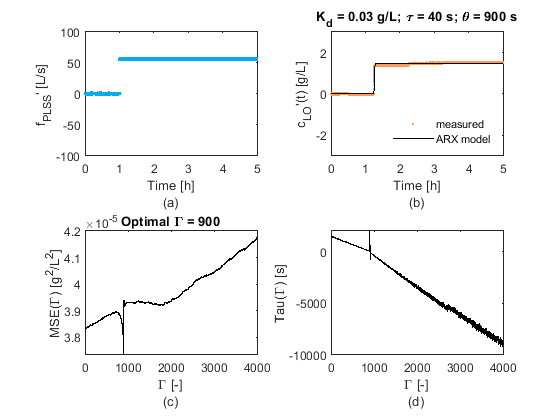

% Create the group of f_PLSS and c_LO
figure()

% PLot f_PLSS
subplot(2,2,1)
plot(STEP_f_PLSS_time_hours, STEP_f_PLSS_f_PLSS_prime, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("f_{PLSS}' [L/s]")
xlabel({"Time [h]";"(a)"})
ylim([-100 100])
xlim([0 STEP_f_PLSS_time_hours(end)])

% Plot c_LO_measured
subplot(2,2,2)
plot(STEP_f_PLSS_time_hours, STEP_f_PLSS_c_LO_measured_prime, '.', 'MarkerSize', 6 ,'Color', orange)
hold on
plot(STEP_f_PLSS_c_LO_transfer_function_time_hours, STEP_f_PLSS_c_LO_transfer_function_results, 'k-','LineWidth', 1)
hold off
STEP_f_PLSS_c_LO_title = sprintf('K_d = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', STEP_f_PLSS_c_LO_Kp_optimal, STEP_f_PLSS_c_LO_tau_optimal, STEP_f_PLSS_c_LO_theta_optimal);
title(STEP_f_PLSS_c_LO_title)
legend({'measured', 'ARX model'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{LO}'(t) [g/L]")
xlabel({"Time [h]";"(b)"})
ylim([-3 3])
xlim([0 STEP_f_PLSS_time_hours(end)])

% Plot the MSE
subplot(2,2,3)
plot([0:gamma_bound], STEP_f_PLSS_c_LO_MSE, 'k-','LineWidth', 1)
STEP_f_PLSS_c_LO_MSE_title = sprintf('Optimal \\Gamma = %.0f', STEP_f_PLSS_c_LO_gamma_optimal);
title(STEP_f_PLSS_c_LO_MSE_title)
ylabel("MSE(\Gamma) [g^{2}/L^{2}]")
xlabel({"\Gamma [-]";"(c)"})
xlim([0 gamma_bound])

% Plot gamma
subplot(2,2,4)
plot([0:gamma_bound], STEP_f_PLSS_c_LO_tau, 'k-','LineWidth', 1)
ylabel("Tau(\Gamma) [s]")
xlabel({"\Gamma [-]";"(d)"})
xlim([0 gamma_bound])

% Save the current figure
print('controller_tuning/output/feedforward/step_f_PLSS_c_LO_prime_ARX_model', '-dpng', '-r600')